t=0:0.01:1;
f=2;
fs=f*2*250;
ts=-5:1/fs:5;
w=2*pi*f;
y=@(t) sin(w*t);
[q,u]=SDK(y(ts),ts);
z=0;
for k=1:length(ts)
    z=z+q(k).*sinc(w*(t-ts(k)));
end
c=max(y(t))./max(z);
z=z.*c

z =    -0.0030    0.1229    0.2471    0.3676    0.4824    0.5893    0.6867    0.7729    0.8467    0.9067    0.9523    0.9827    0.9977    0.9971    0.9810    0.9498    0.9039    0.8439    0.7708    0.6856    0.5894    0.4837    0.3701    0.2503    0.1261   -0.0003   -0.1270   -0.2517   -0.3723   -0.4868   -0.5933   -0.6901   -0.7754   -0.8482   -0.9072   -0.9517   -0.9812   -0.9953   -0.9940   -0.9774   -0.9458   -0.8997   -0.8398   -0.7670   -0.6823   -0.5869   -0.4821   -0.3695   -0.2507   -0.1277


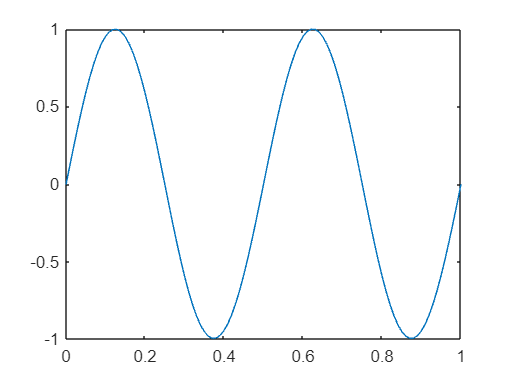

plot(t,z)

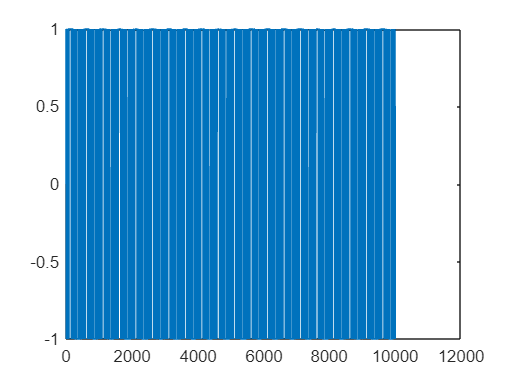

plot(q)

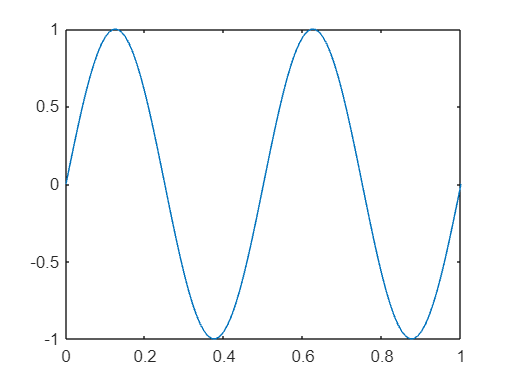

plot(t,y(t))

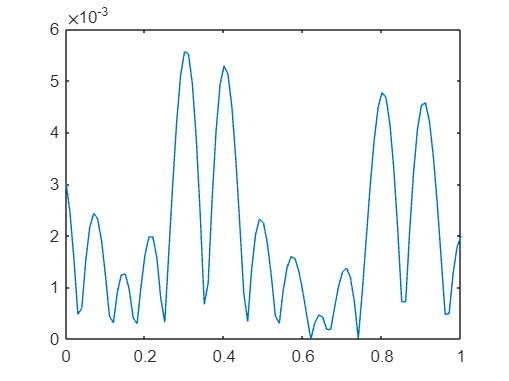

plot(t,abs(y(t)-z))

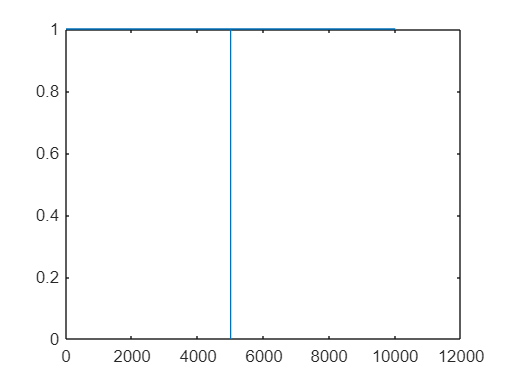

plot(abs(fftshift(q)))

function [q,u]=SDK(y,t)
    q=zeros(1,length(t));
    u=zeros(1,length(t));
    u(1)=0.9;
    for i=2:length(t)
        q(i)=sign(u(i-1)+y(i));
        u(i)=u(i-1)+y(i)-q(i);
    end
end